## Ann Fiegel - Class Project Part 2

Module 1, Project Bank Question 3

Autonomous Cart Speed Profile:

A small autonomous cart follows a speed profile over time modeled by v(t) = -0.2(t - 10)^2 + 20 from 0<=t<=20

Part 1) Implement v(t) and evaluate it on t = 0:0.2:20


t = [0:0.2:20] % stating the values of t that will be used to evaluate v(t)

t =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000



function speed = v(t) % creating a function for v(t)
n = numel(t); % stating that the return of this function needs to be an array of the same size as t. 
speed = zeros(size(t)); % stating that the ruturn speed will start as a zero vecor of size t, then be filled in using the following loop. 
for k = 1:n % loop for k which holds values one through n.
    ti = t(k);% k calls specific values from t to calculate values for the speed array.
    speed = -0.2 * (t - 10).^2 + 20; % stating the mathmatical operations to do to evaluate v(t)
end % end for loop
end % end of function 

speed = v(t) % running the fuction to evaluate the speed. 

speed =          0    0.7920    1.5680    2.3280    3.0720    3.8000    4.5120    5.2080    5.8880    6.5520    7.2000    7.8320    8.4480    9.0480    9.6320   10.2000   10.7520   11.2880   11.8080   12.3120   12.8000   13.2720   13.7280   14.1680   14.5920   15.0000   15.3920   15.7680   16.1280   16.4720   16.8000   17.1120   17.4080   17.6880   17.9520   18.2000   18.4320   18.6480   18.8480   19.0320   19.2000   19.3520   19.4880   19.6080   19.7120   19.8000   19.8720   19.9280   19.9680   19.9920


Part 2) Plot speed vs time

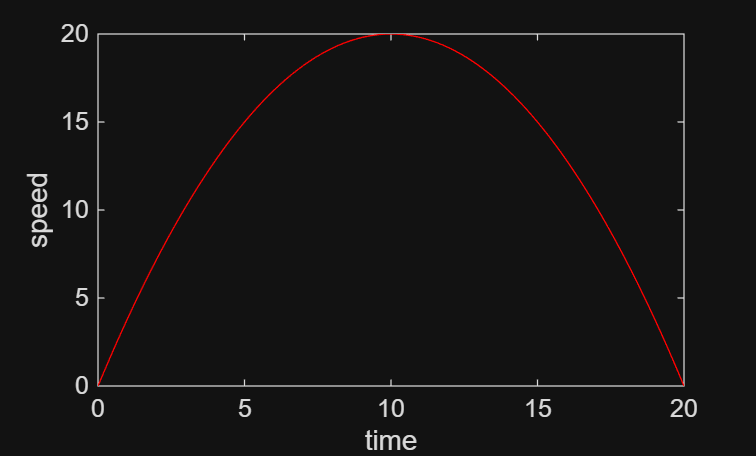


plot(t, speed, 'r-') % plotting speed vs time with a continous red line
xlabel('time') % x axsis label
ylabel('speed') % y axis label

Part 3) Use numerical difference to estimate the acceleration a(t) = delta v/ delta t


function acceleration = a(t, deltaV, deltaT) % create a function that calculates the values for acceleration

    acceleration = deltaV ./ deltaT; % Calculate acceleration using numerical difference

end % end of function 

deltaV = diff(speed); % Calculate the change in speed
deltaT = diff(t); % Calculate the change in time
acceleration = a(t, deltaV, deltaT) % calling the function to return the appriximated accelerations

acceleration =     3.9600    3.8800    3.8000    3.7200    3.6400    3.5600    3.4800    3.4000    3.3200    3.2400    3.1600    3.0800    3.0000    2.9200    2.8400    2.7600    2.6800    2.6000    2.5200    2.4400    2.3600    2.2800    2.2000    2.1200    2.0400    1.9600    1.8800    1.8000    1.7200    1.6400    1.5600    1.4800    1.4000    1.3200    1.2400    1.1600    1.0800    1.0000    0.9200    0.8400    0.7600    0.6800    0.6000    0.5200    0.4400    0.3600    0.2800    0.2000    0.1200    0.0400


Part 4) Plot acceleration vs time on a seperate figure

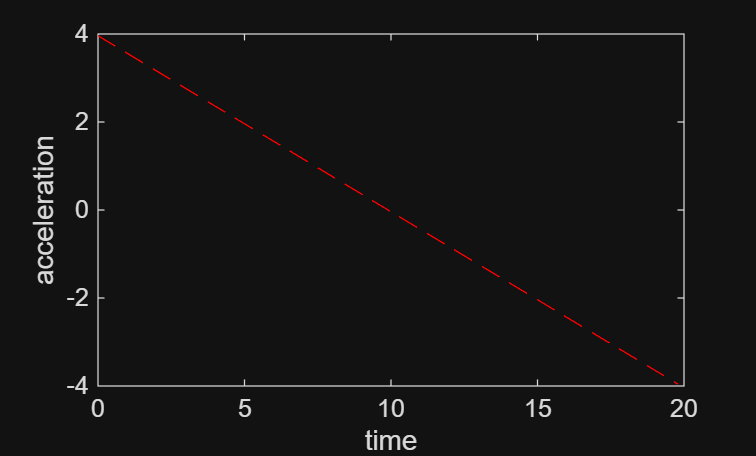

T = t(1:100); % create an array T for time that is of the same size as acceleration and corresponds to the acceleration times

plot(T, acceleration, 'r--') % plotting acceleration vs time with a dashed red line
xlabel('time') % x axis label
ylabel('acceleration') % y axis label

Part 5) Identify the time when speed is maximized and interpret what acceleration is near that time.

Speed is maximized at t = 10. The acceleration at the same point is 0. This is becuase acceleration is the change in speed. Therefore at the point of highest acceleration, the speed is neither increasing or decreacing which is why the acceleration is 0. 